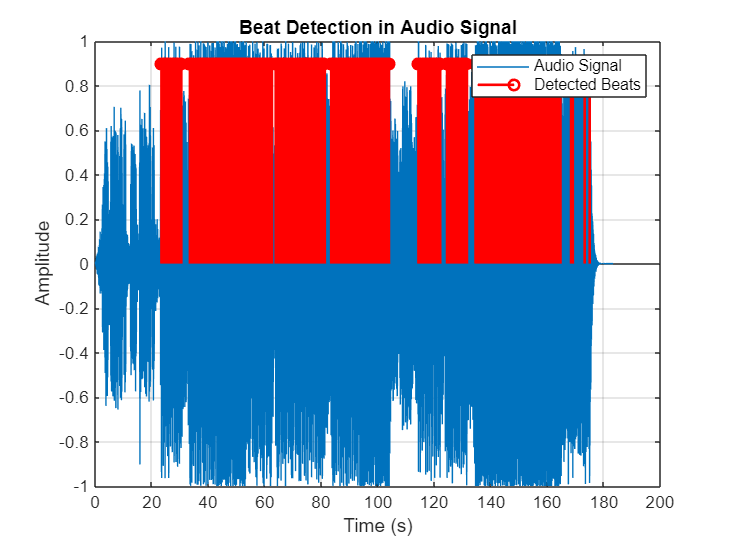

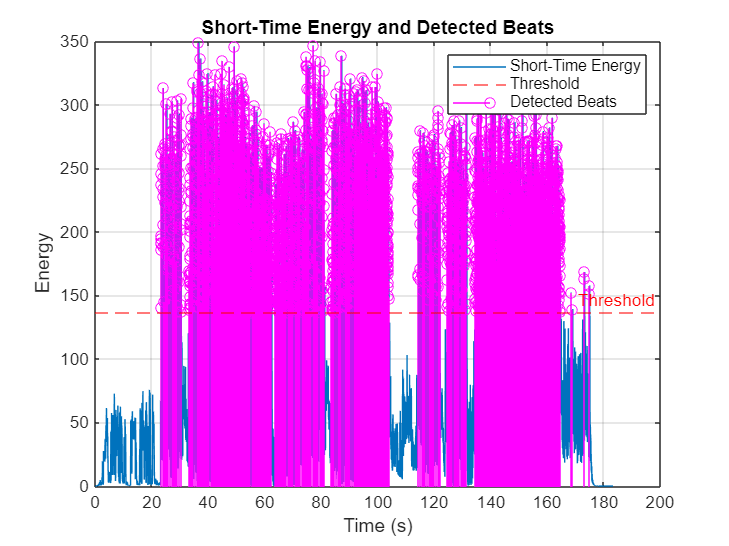

Estimated Tempo: 1766.34 BPM


[file, path] = uigetfile({'eddy.mp3'}, 'Select a Music File');

[y, fs] = audioread(fullfile(path, file));
y = mean(y, 2);
t = (0:length(y)-1) / fs;

frame_len = 1024;
hop_size = 512;
num_frames = floor((length(y) - frame_len) / hop_size);

energy = zeros(1, num_frames);

for i = 1:num_frames
    idx = (i-1) * hop_size + (1:frame_len);
    frame = y(idx);
    energy(i) = sum(frame .^ 2);
end

energy_t = ((1:num_frames) * hop_size) / fs;

threshold = 1.5 * mean(energy);

beats = find(energy > threshold);
beat_times = energy_t(beats);

figure;
plot(t, y); hold on;
stem(beat_times, ones(1, length(beat_times)) * max(y) * 0.9, 'r', 'LineWidth', 1.5);
title('Beat Detection in Audio Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Audio Signal', 'Detected Beats');
grid on;

figure;
plot(energy_t, energy); hold on;
yline(threshold, 'r--', 'Threshold');
stem(beat_times, energy(beats), 'm');
title('Short-Time Energy and Detected Beats');
xlabel('Time (s)');
ylabel('Energy');
legend('Short-Time Energy', 'Threshold', 'Detected Beats');
grid on;

if length(beat_times) > 1
    beat_intervals = diff(beat_times);
    avg_bpm = 60 / mean(beat_intervals);
    fprintf('Estimated Tempo: %.2f BPM\n', avg_bpm);
else
    fprintf('Not enough beats detected to estimate BPM.\n');
end
